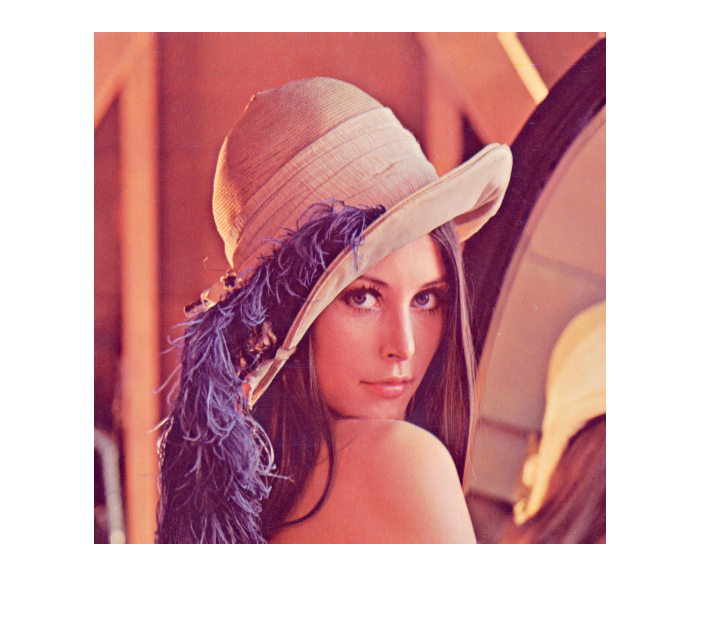

%% data preparation

path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\project_repo\MCoding_project\data\';
% path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\';
% path = 'C:\Users\fosca\Documents\UNIPD\Magistrale_ICT\Multimedia_Coding\project_repo\MCoding_project\Data_Set\Images\';
A = imread(strcat(path,'lena.tiff'));
% A = imread(strcat(path, 'lena_full.jfif'));
imshow(A)

%% Try image with good ol' kmeans first
%reshape image stacking columns
k = 256;
A_r = reshape(A, [],3);
[idx, C] = kmeans(double(A_r), k);
A_k3D = zeros(size(A_r));
C;
% bad implemented with cycles
A_k3D = zeros(size(A_r));
for p = 1:size(idx)
    for i = 1:k
        if idx(p)==i
            A_k3D(p,:) = C(i,:);
        end
    end
end
% % better implementation
% mapfrom = zeros(size(C));
% mapfrom(:,1) = 1:k;
% [sortfrom, sortidx] = sort(mapfrom);
% sortto = C(sortidx);
% A_k3D = zeros(size(A_r));
% A_k3D(:,1) = idx;
% 
% A_k3D = interp1(sortfrom, sortto, A_k3D);


A_k3D = uint8(reshape(A_k3D, size(A)));
imshow(A_k3D)

[d, dImg] = imageDistortion(A, A_k3D);
d

image(dImg)


%%implementing my vector quantization
% target R=8 bit/pixel
% at first we have 24 bit/pixel

%reshape image ready for clustering
A_r = double(reshape(A, [],3))./255;

%get initial rate of the image
% assuming intial is uint8 image range [0,255] values
r = size(A,3)*log2(256);

%we need to run the LBGSplit in a tree with eight levels

C = LBGSplitRecursive(A_r, 1);

% get levels with LBG algorithm
global X;
global M;

X = double(reshape(A, [],3))./255;

M = ones(size(X, 1),1);
c0 = sum(X, 1)/length(X);
C = c0;
%test run
for i = 1:8
    C = LBGCentroidSplit(C);
end



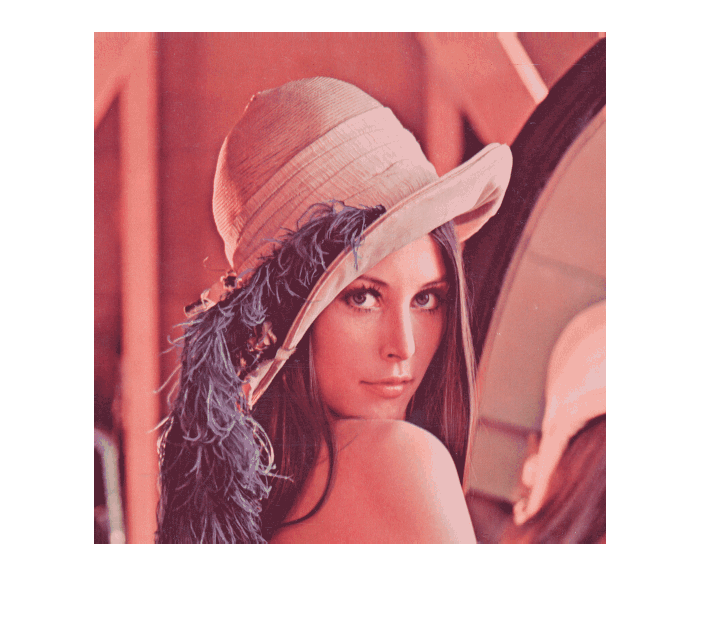

% Quantization
C_img = floor(C*255);

A_r = double(reshape(A, [],3));
A_dist = pdist2(A_r, C_img, "euclidean");
[~, L] = min(A_dist, [], 2);
A_q = zeros(size(A_r));
A_q = C_img(L,:);
A_q = uint8(reshape(A_q, size(A)));
imshow(A_q)

[d, dImg] = imageDistortion(A, A_q);
d

d = 0.0030

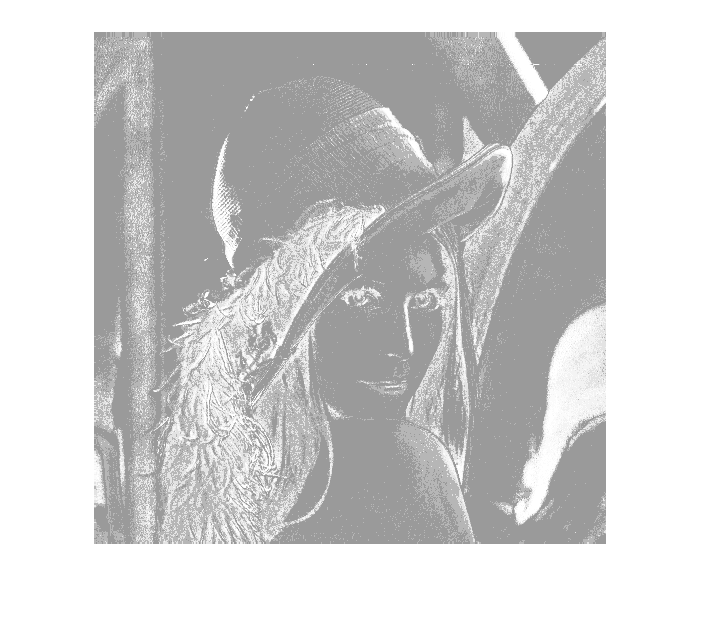


% enhance contrast for easier visualization
J = histeq(dImg);
imshow(J)